# Translate a molecule

Let's import some molecuel and translate it with a 1x3 translation vector.

close all;
atom=import_atom('6x4MMT.gro');

Found .gro file
.gro file imported
Elapsed time is 0.206984 seconds.


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    'Al'    'H'    'O'    'Si'

Atom_numbers =     96    96   576   192

Box_dim =   31.187999999999999  36.060000000000002  10.000000000000000

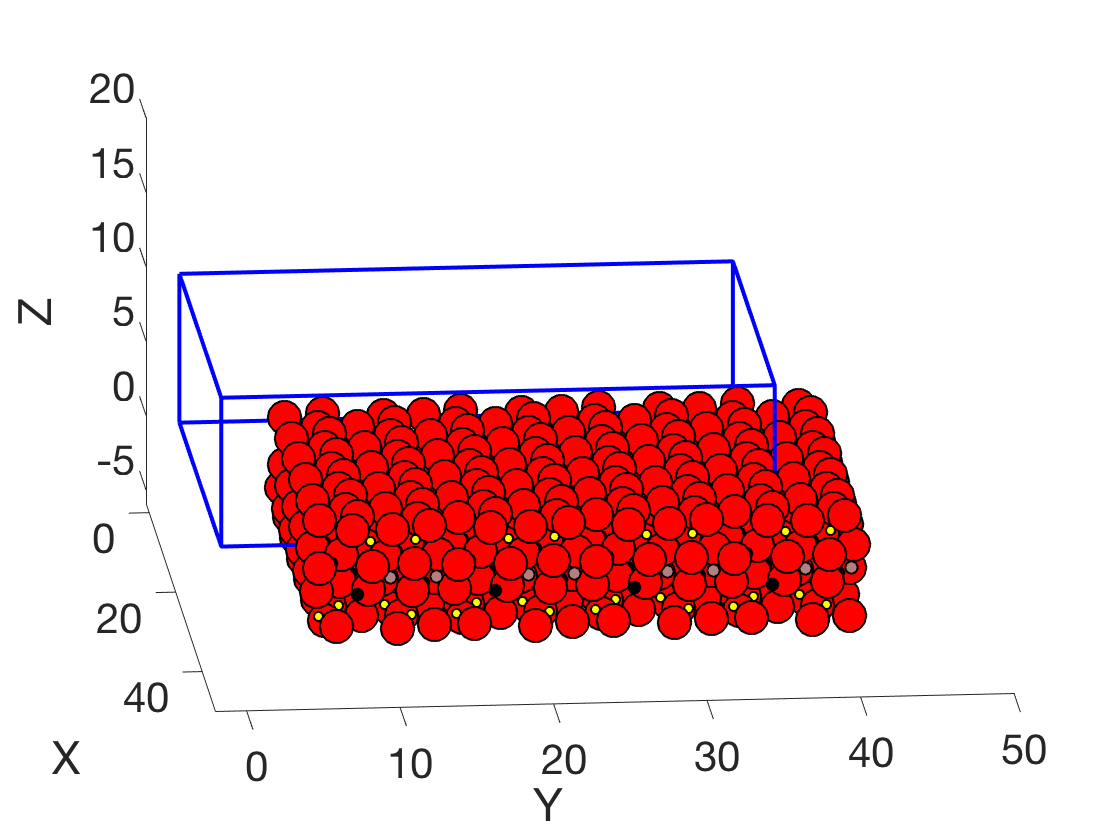

atom=translate_atom(atom,[10 5 -5]); % [10 5 -5] is the translation vector
plot_atom(atom,Box_dim);
view(85,15);

%vmd(atom,Box_dim)